# Pointwise self-convergence for a 1D multipole source

No exact solution is used. On each grid, pressure is sampled at the same spatial points and output times. Successive-grid differences define

and the pointwise observed order is

Change derivativeOrder to 0, 1, 2, ... to test a monopole, dipole, or a higher derivative of delta. The convergence calculation is unchanged.

clear
close all
clc

## Experiment parameters

Lx = 1;
T = 1; %0.40;
xc = 0.487;                 % Off-grid source location
derivativeOrder = 1;        % 0=monopole, 1=dipole, 2=quadrupole, ...
targetField = "pressure";   % "pressure" or "velocity"

% Nested pressure grids: Nx(k+1)-1 = 2*(Nx(k)-1).
NxLevels = [101,201,401];%[41,81,161,321];
nLevels = numel(NxLevels);
if nLevels < 3
    error('At least three grid levels are required for self-convergence.')
end

spatialOrders = [4,4,2];
qValues = [4,2,2];
caseLabels = ["p=4, q=4","p=4, q=2","p=2, q=2"];
nCases = numel(qValues);

% Second-order space: dt=O(dx), so the second-order time discretization
% also contributes O(dx^2). 
% Fourth-order space: dt=O(dx^2), so the second-order time error is O(dx^4) 
% and does not mask spatial order four.
CFL2 = 0.80;
Ctime4 = 0.80;

% All runs are sampled at these same times. The maximum over time is used
% in E_h(x), following the supplied convergence-test code.
nOutputSteps = 400;
outputTimes = linspace(0,T,nOutputSteps+1);

% Delayed Ricker pulse, negligible at t=0.
fPeak = 5;%15;
t0 = 0.3;%0.12;
sourceTime = @(tau) (1-2*(pi*fPeak*(tau-t0)).^2) ...
    .*exp(-(pi*fPeak*(tau-t0)).^2);

medium = AcousticMedium1D.constant(KappaValue=1,BetaValue=1);
p0 = @(x) zeros(size(x));
v0 = @(x) zeros(size(x));

## Common spatial observation grid

outputGrid = GridSpace1D( ...
    Grid1DUnifPrimal([0,Lx],NxLevels(1)));
xOutput = outputGrid.x.pts;

## Optional diagnostic: coarsest-grid MPS stencils

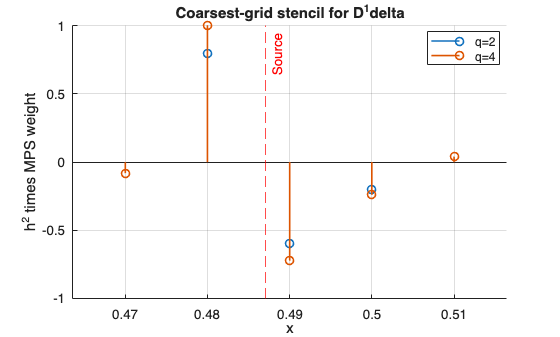

pressureGrid0 = outputGrid;
velocityGrid0 = GridSpace1D(Grid1DUnifDual(pressureGrid0.x));

figure
hold on
for q = unique(qValues)
    if targetField == "pressure"
        stencilGrid = pressureGrid0;
    else
        stencilGrid = velocityGrid0;
    end
    [~,indices,weights] = MPSappx( ...
        stencilGrid,xc,q,derivativeOrder);
    stem(stencilGrid.x.pts(indices), ...
        stencilGrid.h^(derivativeOrder+1)*weights, ...
        LineWidth=1.2,DisplayName=sprintf('q=%d',q))
end
xline(xc,'--r','Source',HandleVisibility='off')
hold off
xlabel('x')
ylabel(sprintf('h^{%d} times MPS weight',derivativeOrder+1))
title(sprintf('Coarsest-grid stencil for D^{%d}delta', ...
    derivativeOrder))
legend(Location='best')
grid on

## Compute solutions on every grid

pressure = cell(nCases,nLevels);
dxUsed = zeros(nCases,nLevels);
dtUsed = zeros(nCases,nLevels);

for iCase = 1:nCases
    spatialOrder = spatialOrders(iCase);
    q = qValues(iCase);

    fprintf('\nRunning spatial order %d, MPS q=%d, derivative s=%d\n', ...
        spatialOrder,q,derivativeOrder)

    for level = 1:nLevels
        pressureGrid = GridSpace1D( ...
            Grid1DUnifPrimal([0,Lx],NxLevels(level)));
        velocityGrid = GridSpace1D( ...
            Grid1DUnifDual(pressureGrid.x));
        dx = pressureGrid.h;

        if spatialOrder == 2
            targetDt = CFL2*dx;
        else
            targetDt = Ctime4*dx^2;
        end
        nTimeSteps = ceil(T/targetDt);
        computationalTimes = linspace(0,T,nTimeSteps+1);

        mps_cmp = MultipoleComponent1D(xc,derivativeOrder,TargetField=targetField);
        mps = MultipoleSrcTerm1D(mps_cmp,sourceTime);
        source = mps.discretize(pressureGrid,velocityGrid,q);

        solver = AcousticSolver1DStaggered( ...
            pressureGrid,computationalTimes,outputGrid,outputTimes, ...
            medium,SpatialOrder=spatialOrder);

        [P,~] = solver.solve(p0,v0,Source=source);
        pressure{iCase,level} = P.values;
        dxUsed(iCase,level) = dx;
        dtUsed(iCase,level) = computationalTimes(2) ...
            -computationalTimes(1);

        fprintf('  Nx=%4d, dx=%9.3e, dt=%9.3e, steps=%d\n', ...
            NxLevels(level),dx,dtUsed(iCase,level),nTimeSteps)
    end
end


Running spatial order 4, MPS q=4, derivative s=1


  Nx= 101, dx=1.000e-02, dt=8.000e-05, steps=12500
  Nx= 201, dx=5.000e-03, dt=2.000e-05, steps=50000
  Nx= 401, dx=2.500e-03, dt=5.000e-06, steps=200000



Running spatial order 4, MPS q=2, derivative s=1


  Nx= 101, dx=1.000e-02, dt=8.000e-05, steps=12500
  Nx= 201, dx=5.000e-03, dt=2.000e-05, steps=50000
  Nx= 401, dx=2.500e-03, dt=5.000e-06, steps=200000



Running spatial order 2, MPS q=2, derivative s=1


  Nx= 101, dx=1.000e-02, dt=8.000e-03, steps=125
  Nx= 201, dx=5.000e-03, dt=4.000e-03, steps=250
  Nx= 401, dx=2.500e-03, dt=2.000e-03, steps=500


## Successive-grid differences and pointwise rates

% difference{iCase,level} compares levels level and level+1.
% rate{iCase,level} compares two consecutive differences and therefore
% requires levels level, level+1, and level+2.
difference = cell(nCases,nLevels-1);
rate = cell(nCases,nLevels-2);

solutionScale = 1;
for iCase = 1:nCases
    for level = 1:nLevels
        solutionScale = max(solutionScale, ...
            max(abs(pressure{iCase,level}),[],'all'));
    end
end
differenceFloor = 1e3*eps(solutionScale);

for iCase = 1:nCases
    for level = 1:nLevels-1
        difference{iCase,level} = max(abs( ...
            pressure{iCase,level}-pressure{iCase,level+1}),[],2);
    end

    for level = 1:nLevels-2
        coarseDifference = difference{iCase,level};
        fineDifference = difference{iCase,level+1};
        rateHere = nan(size(xOutput));
        reliable = coarseDifference > differenceFloor & ...
            fineDifference > differenceFloor;
        rateHere(reliable) = log2( ...
            coarseDifference(reliable)./fineDifference(reliable));
        rate{iCase,level} = rateHere;
    end
end

## Plot successive-grid differences as functions of x

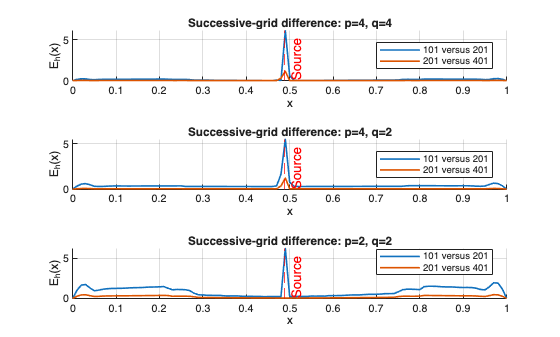

figure
tiledlayout(nCases,1)
for iCase = 1:nCases
    nexttile
    hold on
    for level = 1:nLevels-1
        semilogy(xOutput,max(difference{iCase,level},differenceFloor), ...
            LineWidth=1.2,DisplayName=sprintf('%d versus %d', ...
            NxLevels(level),NxLevels(level+1)))
    end
    xline(xc,'--r','Source',HandleVisibility='off')
    hold off
    xlabel('x')
    ylabel('E_h(x)')
    title(sprintf('Successive-grid difference: %s',caseLabels(iCase)))
    legend(Location='best')
    grid on
end

## Plot pointwise self-convergence rates

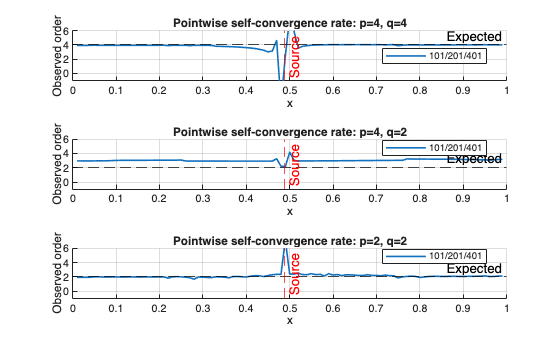

figure
tiledlayout(nCases,1)
for iCase = 1:nCases
    nexttile
    hold on
    for level = 1:nLevels-2
        plot(xOutput,rate{iCase,level},LineWidth=1.2, ...
            DisplayName=sprintf('%d/%d/%d',NxLevels(level), ...
            NxLevels(level+1),NxLevels(level+2)))
    end
    expectedOrder = min(spatialOrders(iCase),qValues(iCase));
    yline(expectedOrder,'--k','Expected',HandleVisibility='off')
    xline(xc,'--r','Source',HandleVisibility='off')
    hold off
    ylim([-1,6])
    xlabel('x')
    ylabel('Observed order')
    title(sprintf('Pointwise self-convergence rate: %s', ...
        caseLabels(iCase)))
    legend(Location='best')
    grid on
end

## Compact rate summary away from unreliable near-zero differences

medianRate = nan(nCases,nLevels-2);
for iCase = 1:nCases
    for level = 1:nLevels-2
        values = rate{iCase,level};
        medianRate(iCase,level) = median(values,'omitnan');
    end
end

spatialOrderColumn = repelem(spatialOrders(:),nLevels-2);
qColumn = repelem(qValues(:),nLevels-2);
coarseNxColumn = repmat(NxLevels(1:end-2).',nCases,1);
middleNxColumn = repmat(NxLevels(2:end-1).',nCases,1);
fineNxColumn = repmat(NxLevels(3:end).',nCases,1);
medianRateColumn = reshape(medianRate.',[],1);

summaryTable = table(spatialOrderColumn,qColumn,coarseNxColumn, ...
    middleNxColumn,fineNxColumn,medianRateColumn, ...
    VariableNames=["SpatialOrder","q","CoarseNx","MiddleNx", ...
    "FineNx","MedianPointwiseRate"])

summaryTable = 3×6 table
    SpatialOrder    q    CoarseNx    MiddleNx    FineNx    MedianPointwiseRate
    ____________    _    ________    ________    ______    ___________________

         4          4      101         201        401            3.9496       
         4          2      101         201        401            3.0119       
         2          2      101         201        401            2.0726       

	Get insights using Copilot
